% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 7;
avgNum = 1;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-06-28-2/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Growth(40x,25mW)_20000_5_2024-06-28-15.08.17.557.csv";
file_path = data_path+file_name;
growth_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth2(40x,25mW)_20000_5_2024-06-28-15.12.40.750.csv";
file_path = strcat(data_path,file_name);
growth_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth3(40x,25mW)_20000_5_2024-06-28-15.16.56.273.csv";
file_path = strcat(data_path,file_name);
growth_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth4(40x,25mW)_20000_5_2024-06-28-15.21.47.410.csv";
file_path = strcat(data_path,file_name);
growth_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth5(40x,25mW)_20000_5_2024-06-28-15.25.51.533.csv";
file_path = strcat(data_path,file_name);
growth_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth6(40x,25mW)_20000_5_2024-06-28-15.29.47.597.csv";
file_path = strcat(data_path,file_name);
growth_6 = csvread(file_path, numMetadataRows, 0);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-06-28-3/";

file_name = "Growth(40x,25mW)_20000_5_2024-06-28-15.55.42.290.csv";
file_path = data_path+file_name;
growth_1SD = csvread(file_path, numMetadataRows, 0);

file_name = "Growth2(40x,25mW)_20000_5_2024-06-28-15.59.30.007.csv";
file_path = strcat(data_path,file_name);
growth_2SD = csvread(file_path, numMetadataRows, 0);

file_name = "Growth3(40x,25mW)_20000_5_2024-06-28-16.03.23.117.csv";
file_path = strcat(data_path,file_name);
growth_3SD = csvread(file_path, numMetadataRows, 0);

file_name = "Growth4(40x,25mW)_20000_5_2024-06-28-16.07.20.933.csv";
file_path = strcat(data_path,file_name);
growth_4SD = csvread(file_path, numMetadataRows, 0);

file_name = "Growth5(40x,25mW)_20000_5_2024-06-28-16.11.23.827.csv";
file_path = strcat(data_path,file_name);
growth_5SD = csvread(file_path, numMetadataRows, 0);

file_name = "Growth6(40x,25mW)_20000_5_2024-06-28-16.15.58.143.csv";
file_path = strcat(data_path,file_name);
growth_6SD = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [growth_6(1, 1:3101) ; nist1(23:end, :)];

poly1 = readmatrix('Data/Polystyrene_1_2024-05-07-10.40.30.583.csv'); 
poly = mean(poly1(2:end,:));

Si1 = readmatrix('Data/Silicon_2_2024-05-07-10.25.23.800.csv'); 
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = growth_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
growth_1(:, growth_1(1, :) <= t1) = [];
growth_1(:, growth_1(1, :) >= t2) = [];
growth_2(:, growth_2(1, :) <= t1) = [];
growth_2(:, growth_2(1, :) >= t2) = [];
growth_3(:, growth_3(1, :) <= t1) = [];
growth_3(:, growth_3(1, :) >= t2) = [];
growth_4(:, growth_4(1, :) <= t1) = [];
growth_4(:, growth_4(1, :) >= t2) = [];
growth_5(:, growth_5(1, :) <= t1) = [];
growth_5(:, growth_5(1, :) >= t2) = [];
growth_6(:, growth_6(1, :) <= t1) = [];
growth_6(:, growth_6(1, :) >= t2) = [];
growth_1SD(:, growth_1SD(1, :) <= t1) = [];
growth_1SD(:, growth_1SD(1, :) >= t2) = [];
growth_2SD(:, growth_2SD(1, :) <= t1) = [];
growth_2SD(:, growth_2SD(1, :) >= t2) = [];
growth_3SD(:, growth_3SD(1, :) <= t1) = [];
growth_3SD(:, growth_3SD(1, :) >= t2) = [];
growth_4SD(:, growth_4SD(1, :) <= t1) = [];
growth_4SD(:, growth_4SD(1, :) >= t2) = [];
growth_5SD(:, growth_5SD(1, :) <= t1) = [];
growth_5SD(:, growth_5SD(1, :) >= t2) = [];
growth_6SD(:, growth_6SD(1, :) <= t1) = [];
growth_6SD(:, growth_6SD(1, :) >= t2) = [];

shifts = wavenumber;

grow1 = growth_1(2:end, :);
grow2 = growth_2(2:end, :);
grow3 = growth_3(2:end, :);
grow4 = growth_4(2:end, :);
grow5 = growth_5(2:end, :);
grow6 = growth_6(2:end, :);
grow1SD = growth_1SD(2:end, :);
grow2SD = growth_2SD(2:end, :);
grow3SD = growth_3SD(2:end, :);
grow4SD = growth_4SD(2:end, :);
grow5SD = growth_5SD(2:end, :);
grow6SD = growth_6SD(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

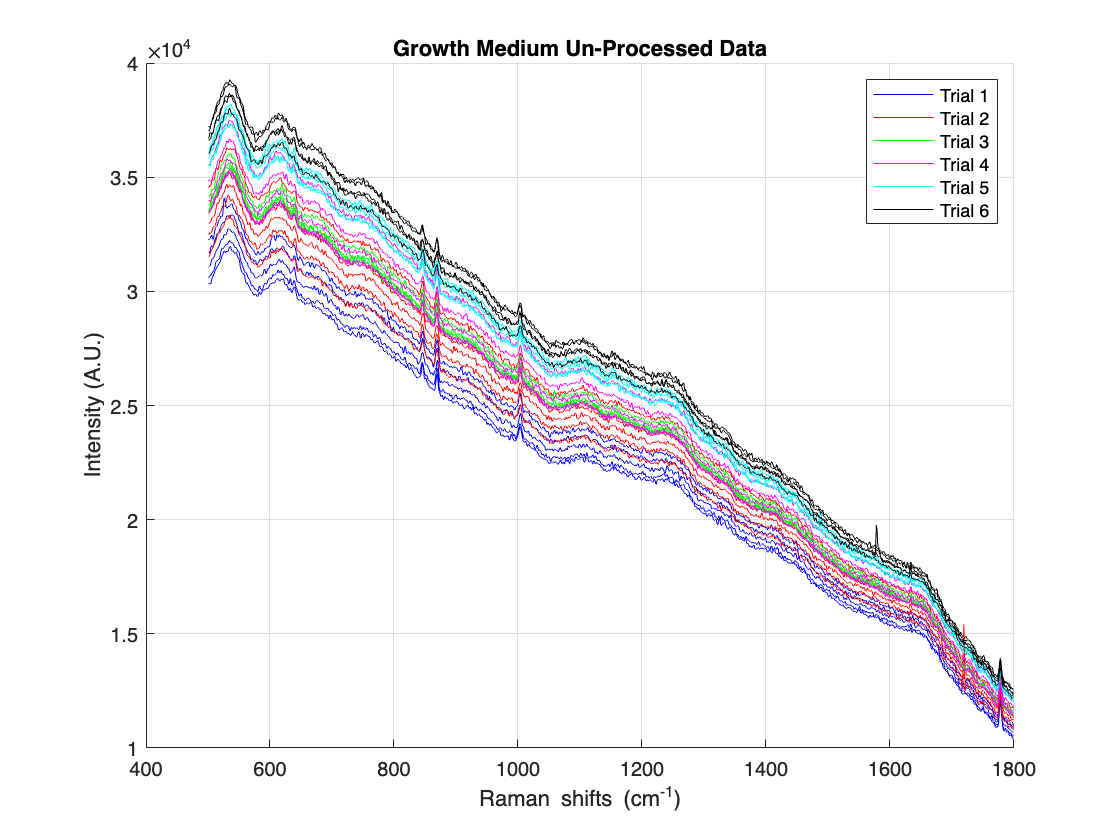

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, grow1(1,:), '-b');
plot(wavenumber, grow2(1,:), '-r');
plot(wavenumber, grow3(1,:), '-g');
plot(wavenumber, grow4(1,:), '-m');
plot(wavenumber, grow5(1,:), '-c');
plot(wavenumber, grow6(1,:), '-k');
plot(wavenumber, grow1(2:end,:), '-b');
plot(wavenumber, grow2(2:end,:), '-r');
plot(wavenumber, grow3(2:end,:), '-g');
plot(wavenumber, grow4(2:end,:), '-m');
plot(wavenumber, grow5(2:end,:), '-c');
plot(wavenumber, grow6(2:end,:), '-k');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Un-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6');
hold off;

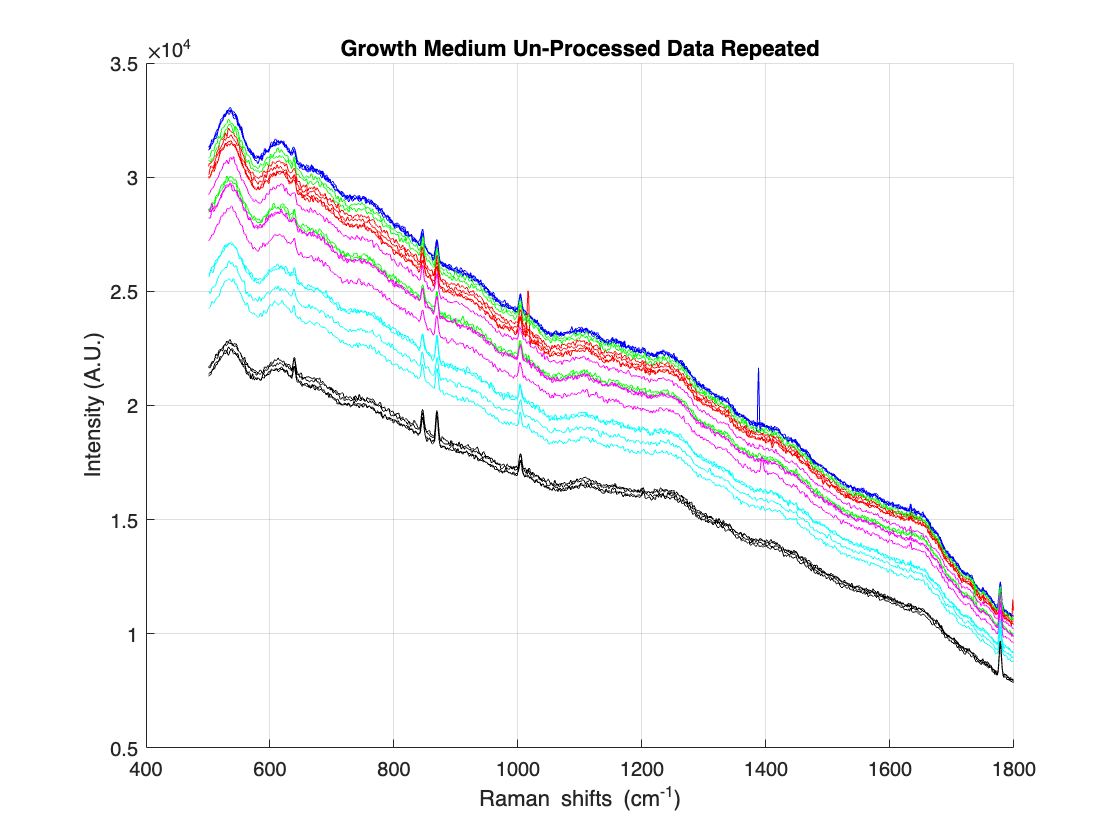

figure;
hold on;
grid on;
plot(wavenumber, grow1SD(2:end, :), '-b');
plot(wavenumber, grow2SD(2:end, :), '-r');
plot(wavenumber, grow3SD(2:end, :), '-g');
plot(wavenumber, grow4SD(2:end, :), '-m');
plot(wavenumber, grow5SD(2:end, :), '-c');
plot(wavenumber, grow6SD(2:end, :), '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Un-Processed Data Repeated');
hold off;

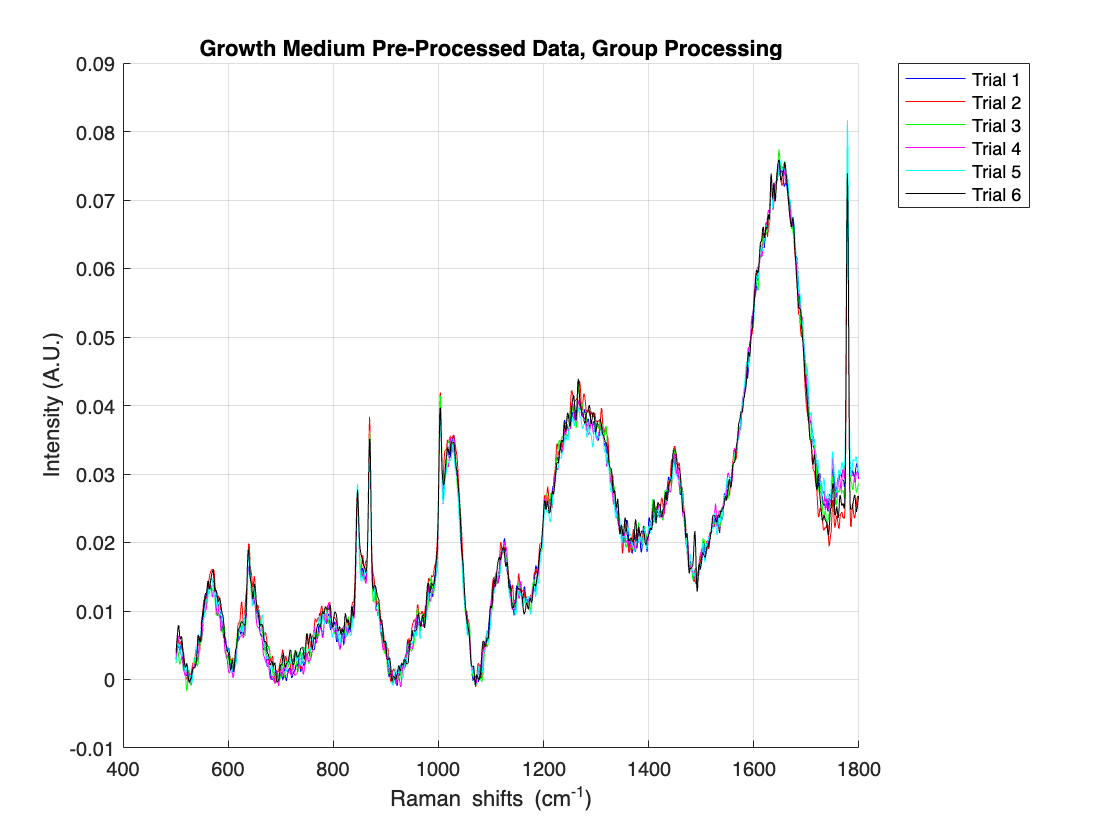

% Preprocessing the data

pro_grow1 = apply(grow1, [6,1,10,11,8,2,5,6,7]);
pro_grow2 = apply(grow2, [6,1,10,11,8,2,5,6,7]);
pro_grow3 = apply(grow3, [6,1,10,11,8,2,5,6,7]);
pro_grow4 = apply(grow4, [6,1,10,11,8,2,5,6,7]);
pro_grow5 = apply(grow5, [6,1,10,11,8,2,5,6,7]);
pro_grow6 = apply(grow6, [6,1,10,11,8,2,5,6,7]);
pro_grow1SD = apply(grow1SD, [6,1,10,11,8,2,5,6,7]);
pro_grow2SD = apply(grow2SD, [6,1,10,11,8,2,5,6,7]);
pro_grow3SD = apply(grow3SD, [6,1,10,11,8,2,5,6,7]);
pro_grow4SD = apply(grow4SD, [6,1,10,11,8,2,5,6,7]);
pro_grow5SD = apply(grow5SD, [6,1,10,11,8,2,5,6,7]);
pro_grow6SD = apply(grow6SD, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

avgNum = 4;

grow = [grow1;grow2;grow3;grow4;grow5;grow6];
pro_grow = apply(grow, [6,1,10,11,8,2,5,6,7]);

growSD = [grow1SD;grow2SD;grow3SD;grow4SD;grow5SD;grow6SD];
pro_growSD = apply(growSD, [6,1,10,11,8,2,5,6,7]);

grow_comb = [grow1;grow1SD];
pro_grow_comb = apply(grow_comb, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_grow(1,:), '-b');
plot(wavenumber, pro_grow(2,:), '-r');
plot(wavenumber, pro_grow(3,:), '-g');
plot(wavenumber, pro_grow(4,:), '-m');
plot(wavenumber, pro_grow(5,:), '-c');
plot(wavenumber, pro_grow(6,:), '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data, Group Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6', 'Location', 'northeastoutside');
hold off;

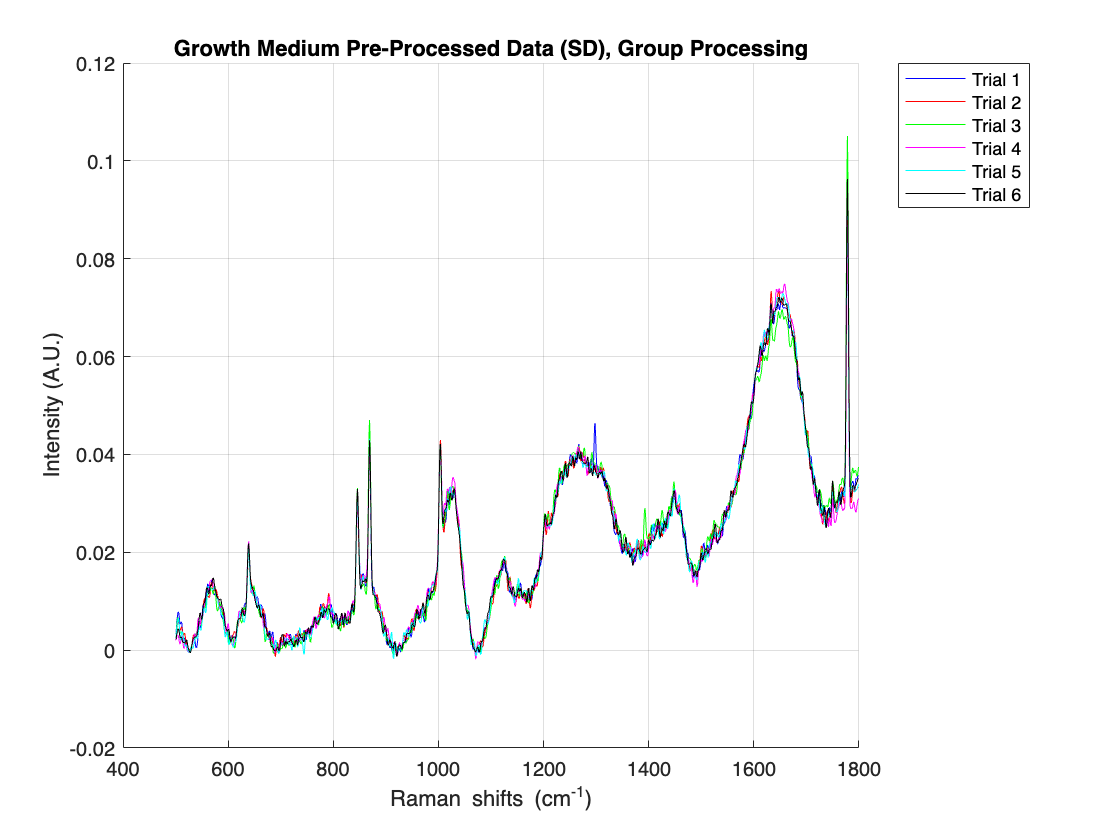

figure;
hold on;
grid on;
plot(wavenumber, pro_growSD(1,:), '-b');
plot(wavenumber, pro_growSD(2,:), '-r');
plot(wavenumber, pro_growSD(3,:), '-g');
plot(wavenumber, pro_growSD(4,:), '-m');
plot(wavenumber, pro_growSD(5,:), '-c');
plot(wavenumber, pro_growSD(6,:), '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (SD), Group Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6', 'Location', 'northeastoutside');
hold off;

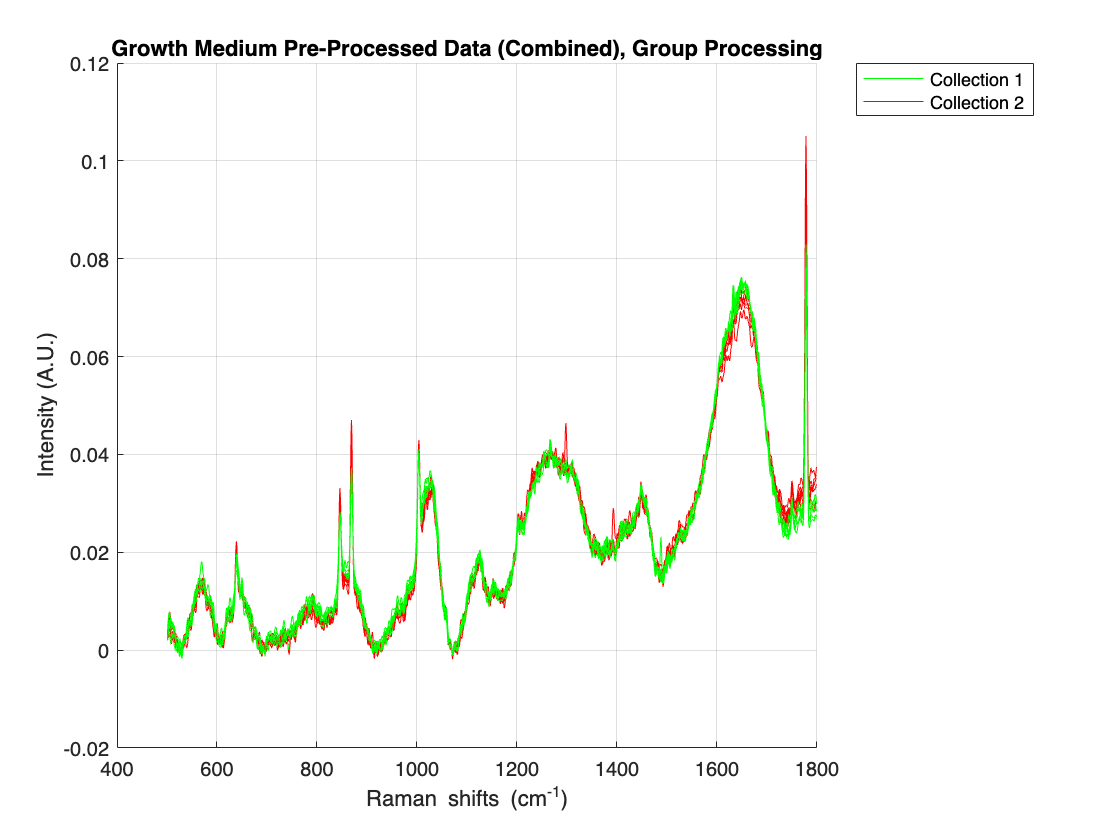

figure;
hold on;
grid on;
plot(wavenumber, pro_grow(1,:), '-g');
plot(wavenumber, pro_growSD(1,:), '-r');
plot(wavenumber, pro_growSD(2,:), '-r');
plot(wavenumber, pro_growSD(3,:), '-r');
plot(wavenumber, pro_growSD(4,:), '-r');
plot(wavenumber, pro_growSD(5,:), '-r');
plot(wavenumber, pro_growSD(6,:), '-r');
plot(wavenumber, pro_grow(2,:), '-g');
plot(wavenumber, pro_grow(3,:), '-g');
plot(wavenumber, pro_grow(4,:), '-g');
plot(wavenumber, pro_grow(5,:), '-g');
plot(wavenumber, pro_grow(6,:), '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (Combined), Group Processing');
legend('Collection 1','Collection 2', 'Location', 'northeastoutside');
hold off;

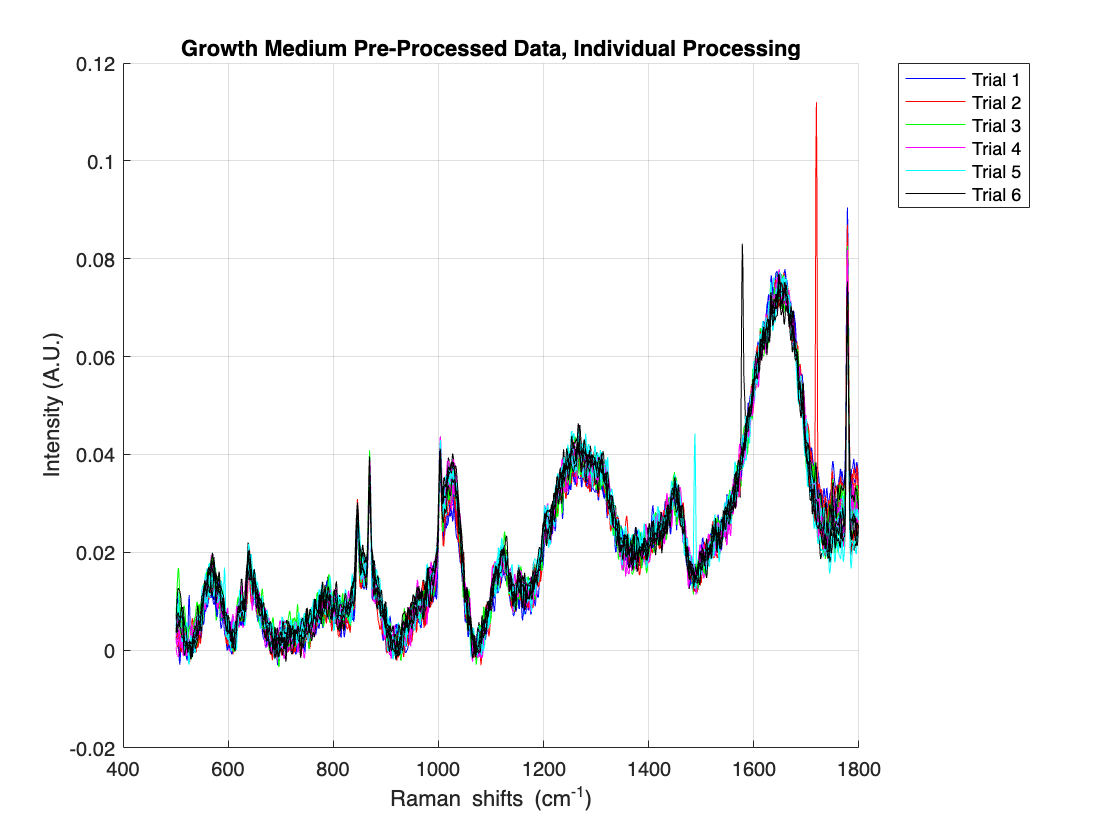


figure;
hold on;
grid on;
plot(wavenumber, pro_grow1(1,:), '-b');
plot(wavenumber, pro_grow2(1,:), '-r');
plot(wavenumber, pro_grow3(1,:), '-g');
plot(wavenumber, pro_grow4(1,:), '-m');
plot(wavenumber, pro_grow5(1,:), '-c');
plot(wavenumber, pro_grow6(1,:), '-k');
plot(wavenumber, pro_grow1(2:end,:), '-b');
plot(wavenumber, pro_grow2(2:end,:), '-r');
plot(wavenumber, pro_grow3(2:end,:), '-g');
plot(wavenumber, pro_grow4(2:end,:), '-m');
plot(wavenumber, pro_grow5(2:end,:), '-c');
plot(wavenumber, pro_grow6(2:end,:), '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data, Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6', 'Location', 'northeastoutside');
hold off;

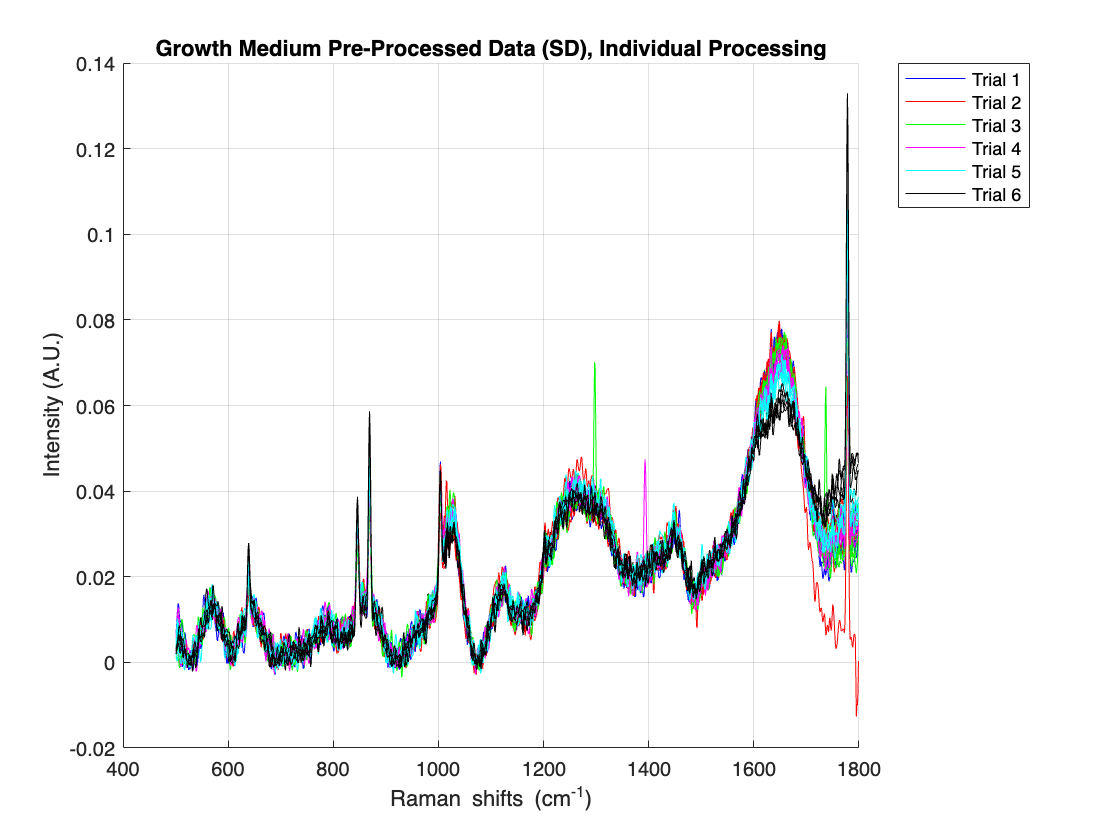

figure;
hold on;
grid on;
plot(wavenumber, pro_grow1SD(1,:), '-b');
plot(wavenumber, pro_grow2SD(1,:), '-r');
plot(wavenumber, pro_grow3SD(1,:), '-g');
plot(wavenumber, pro_grow4SD(1,:), '-m');
plot(wavenumber, pro_grow5SD(1,:), '-c');
plot(wavenumber, pro_grow6SD(1,:), '-k');
plot(wavenumber, pro_grow1SD(2:end,:), '-b');
plot(wavenumber, pro_grow2SD(2:end,:), '-r');
plot(wavenumber, pro_grow3SD(2:end,:), '-g');
plot(wavenumber, pro_grow4SD(2:end,:), '-m');
plot(wavenumber, pro_grow5SD(2:end,:), '-c');
plot(wavenumber, pro_grow6SD(2:end,:), '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (SD), Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6', 'Location', 'northeastoutside');
hold off;

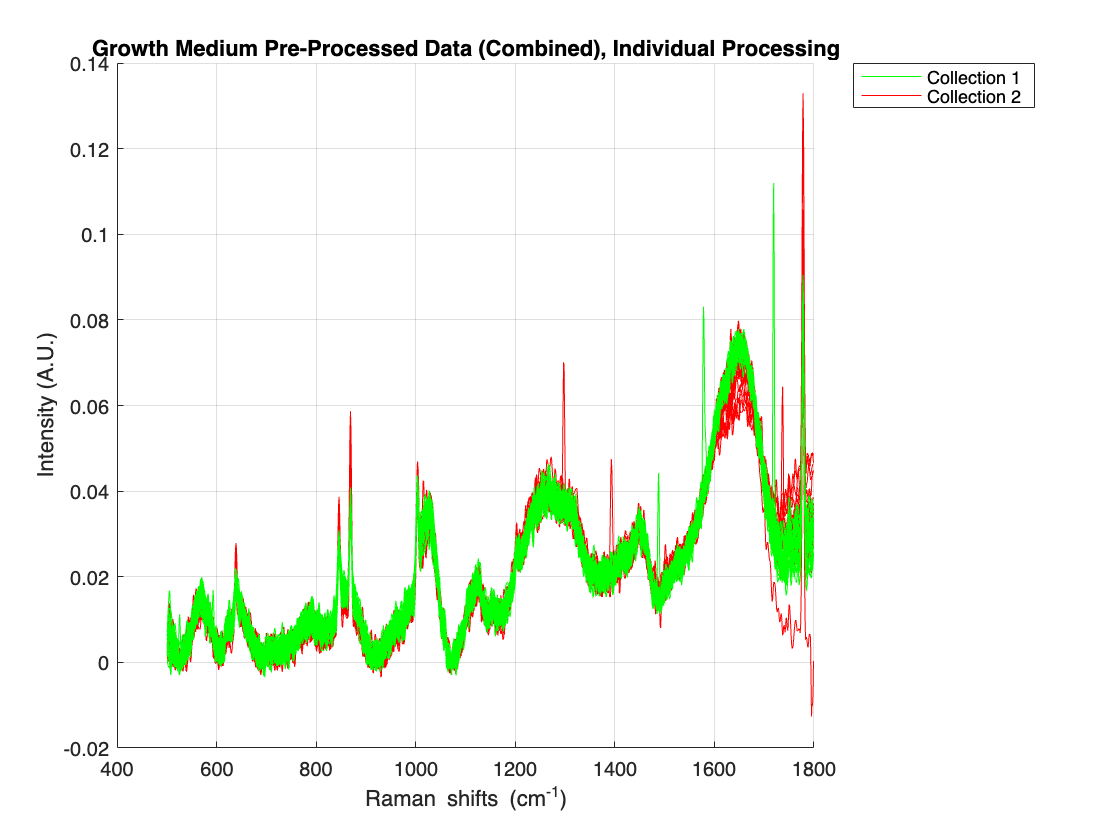

figure;
hold on;
grid on;
plot(wavenumber, pro_grow1(1,:), '-g');
plot(wavenumber, pro_grow1SD(1,:), '-r');
plot(wavenumber, pro_grow2SD(1,:), '-r');
plot(wavenumber, pro_grow3SD(1,:), '-r');
plot(wavenumber, pro_grow4SD(1,:), '-r');
plot(wavenumber, pro_grow5SD(1,:), '-r');
plot(wavenumber, pro_grow6SD(1,:), '-r');
plot(wavenumber, pro_grow1SD(2:end,:), '-r');
plot(wavenumber, pro_grow2SD(2:end,:), '-r');
plot(wavenumber, pro_grow3SD(2:end,:), '-r');
plot(wavenumber, pro_grow4SD(2:end,:), '-r');
plot(wavenumber, pro_grow5SD(2:end,:), '-r');
plot(wavenumber, pro_grow6SD(2:end,:), '-r');
plot(wavenumber, pro_grow2(1,:), '-g');
plot(wavenumber, pro_grow3(1,:), '-g');
plot(wavenumber, pro_grow4(1,:), '-g');
plot(wavenumber, pro_grow5(1,:), '-g');
plot(wavenumber, pro_grow6(1,:), '-g');
plot(wavenumber, pro_grow1(2:end,:), '-g');
plot(wavenumber, pro_grow2(2:end,:), '-g');
plot(wavenumber, pro_grow3(2:end,:), '-g');
plot(wavenumber, pro_grow4(2:end,:), '-g');
plot(wavenumber, pro_grow5(2:end,:), '-g');
plot(wavenumber, pro_grow6(2:end,:), '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (Combined), Individual Processing');
legend('Collection 1','Collection 2', 'Location', 'northeastoutside');
hold off;

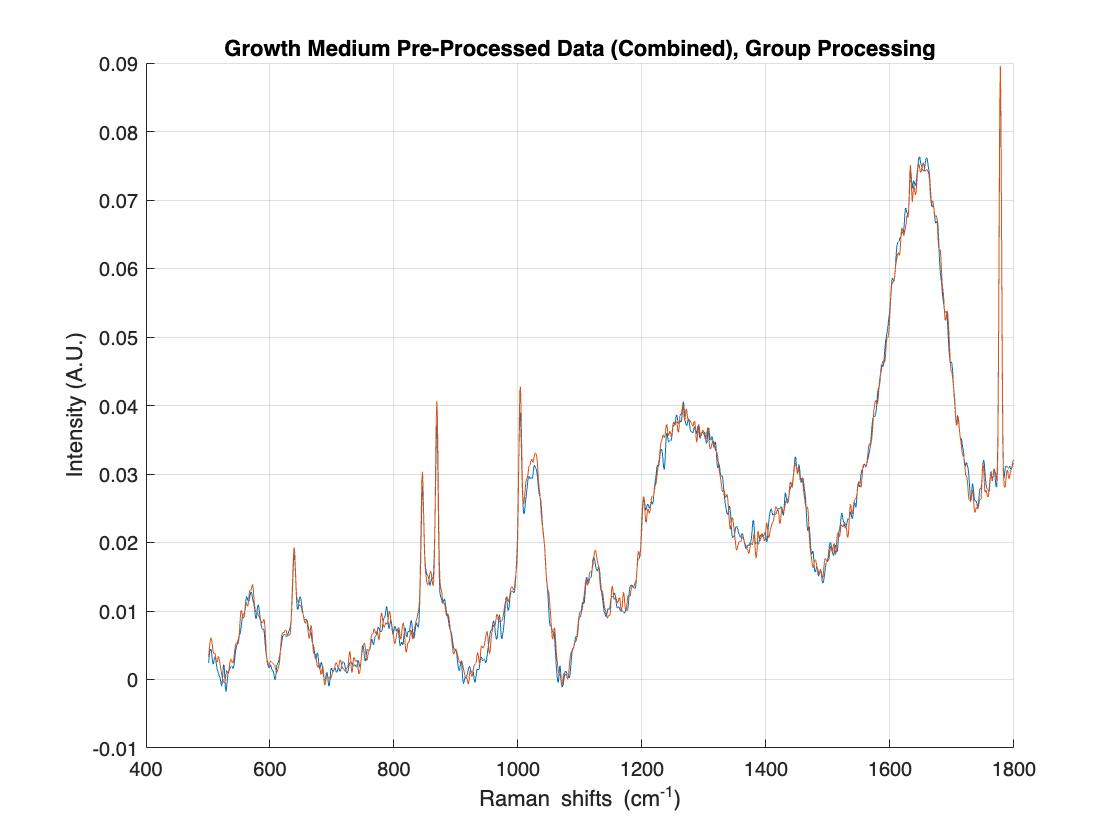

figure;
hold on;
grid on;
plot(wavenumber, pro_grow_comb, '-');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (Combined), Group Processing');
hold off;

% Data for 417 cm^-1 peak
Trial1 = pro_grow1(:, 117);
Trial2 = pro_grow2(:, 117);
Trial3 = pro_grow3(:, 117);
Trial4 = pro_grow4(:, 117);
Trial5 = pro_grow5(:, 117);
Trial6 = pro_grow6(:, 117);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);
av_Trial3 = mean(Trial3);
av_Trial4 = mean(Trial4);
av_Trial5 = mean(Trial5);
av_Trial6 = mean(Trial6);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);
std_Trial3 = std(Trial3);
std_Trial4 = std(Trial4);
std_Trial5 = std(Trial5);
std_Trial6 = std(Trial6);

% Number of spectra in each collection
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);
n_Trial3 = size(Trial3, 1);
n_Trial4 = size(Trial4, 1);
n_Trial5 = size(Trial5, 1);
n_Trial6 = size(Trial6, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);
[t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3] = perform_ttest(av_Trial1, av_Trial3, std_Trial1, std_Trial3, n_Trial1, n_Trial3);
[t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4] = perform_ttest(av_Trial1, av_Trial4, std_Trial1, std_Trial4, n_Trial1, n_Trial4);
[t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5] = perform_ttest(av_Trial1, av_Trial5, std_Trial1, std_Trial5, n_Trial1, n_Trial5);
[t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6] = perform_ttest(av_Trial1, av_Trial6, std_Trial1, std_Trial6, n_Trial1, n_Trial6);
[t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3] = perform_ttest(av_Trial2, av_Trial3, std_Trial2, std_Trial3, n_Trial2, n_Trial3);
[t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4] = perform_ttest(av_Trial2, av_Trial4, std_Trial2, std_Trial4, n_Trial2, n_Trial4);
[t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5] = perform_ttest(av_Trial2, av_Trial5, std_Trial2, std_Trial5, n_Trial2, n_Trial5);
[t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6] = perform_ttest(av_Trial2, av_Trial6, std_Trial2, std_Trial6, n_Trial2, n_Trial6);
[t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4] = perform_ttest(av_Trial3, av_Trial4, std_Trial3, std_Trial4, n_Trial3, n_Trial4);
[t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5] = perform_ttest(av_Trial3, av_Trial5, std_Trial3, std_Trial5, n_Trial3, n_Trial5);
[t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6] = perform_ttest(av_Trial3, av_Trial6, std_Trial3, std_Trial6, n_Trial3, n_Trial6);
[t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5] = perform_ttest(av_Trial4, av_Trial5, std_Trial4, std_Trial5, n_Trial4, n_Trial5);
[t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6] = perform_ttest(av_Trial4, av_Trial6, std_Trial4, std_Trial6, n_Trial4, n_Trial6);
[t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6] = perform_ttest(av_Trial5, av_Trial6, std_Trial5, std_Trial6, n_Trial5, n_Trial6);

% Display results
fprintf('t-test and p values for pairwise comparisons at 417 cm^-1 peak:\n');

t-test and p values for pairwise comparisons at 417 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = -0.9582, p = 0.3699, df = 6.9990


fprintf('Trial 1 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial3, p_Trial1_Trial3, df_Trial1_Trial3);

Trial 1 vs Trial 3: t = -3.2570, p = 0.0126, df = 7.5333


fprintf('Trial 1 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial4, p_Trial1_Trial4, df_Trial1_Trial4);

Trial 1 vs Trial 4: t = -3.2232, p = 0.0124, df = 7.9133


fprintf('Trial 1 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial5, p_Trial1_Trial5, df_Trial1_Trial5);

Trial 1 vs Trial 5: t = -0.9228, p = 0.3850, df = 7.4652


fprintf('Trial 1 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial6, p_Trial1_Trial6, df_Trial1_Trial6);

Trial 1 vs Trial 6: t = -2.4198, p = 0.0488, df = 6.4942


fprintf('Trial 2 vs Trial 3: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial3, p_Trial2_Trial3, df_Trial2_Trial3);

Trial 2 vs Trial 3: t = -1.8259, p = 0.1060, df = 7.8403


fprintf('Trial 2 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial4, p_Trial2_Trial4, df_Trial2_Trial4);

Trial 2 vs Trial 4: t = -1.5050, p = 0.1787, df = 6.5804


fprintf('Trial 2 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial5, p_Trial2_Trial5, df_Trial2_Trial5);

Trial 2 vs Trial 5: t = 0.0974, p = 0.9248, df = 7.8809


fprintf('Trial 2 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial2_Trial6, p_Trial2_Trial6, df_Trial2_Trial6);

Trial 2 vs Trial 6: t = -0.6823, p = 0.5241, df = 5.2325


fprintf('Trial 3 vs Trial 4: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial4, p_Trial3_Trial4, df_Trial3_Trial4);

Trial 3 vs Trial 4: t = 0.6218, p = 0.5534, df = 7.1509


fprintf('Trial 3 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial5, p_Trial3_Trial5, df_Trial3_Trial5);

Trial 3 vs Trial 5: t = 2.0572, p = 0.0737, df = 7.9968


fprintf('Trial 3 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial3_Trial6, p_Trial3_Trial6, df_Trial3_Trial6);

Trial 3 vs Trial 6: t = 1.7645, p = 0.1315, df = 5.6124


fprintf('Trial 4 vs Trial 5: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial5, p_Trial4_Trial5, df_Trial4_Trial5);

Trial 4 vs Trial 5: t = 1.7639, p = 0.1207, df = 7.0722


fprintf('Trial 4 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial4_Trial6, p_Trial4_Trial6, df_Trial4_Trial6);

Trial 4 vs Trial 6: t = 1.4160, p = 0.2002, df = 6.9115


fprintf('Trial 5 vs Trial 6: t = %.4f, p = %.4f, df = %.4f\n', t_Trial5_Trial6, p_Trial5_Trial6, df_Trial5_Trial6);

Trial 5 vs Trial 6: t = -0.8918, p = 0.4094, df = 5.5539


function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end



